## **load preprocessed .set file from EEGLAB to FieldTrip**

%% load preprocessed .set file from EEGLAB to FieldTrip
filename = 'C:\Users\srostam7\SaraDrive\Thesis\Sessions_Data\pipeline1(mine)\Session1_ds_lp_vr_ref_1chrej_ica_icrej_intpl_hp01_ep_bc_trej.set'; 
cfg = []; 
cfg.dataset = filename;
hdr = ft_read_header(filename);
event = ft_read_event(filename);
ft_data1 = ft_preprocessing(cfg);
ft_data1.hdr = hdr;

## **Calculate ERPs**

cfg = []; 
% cfg.trials = find(ft_data1.trialinfo==1);
erp_vis_all = ft_timelockanalysis(cfg, ft_data1);

the input is raw data with 31 channels and 579 trials


 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In ft_selectdata at line 196
 In ft_timelockanalysis at line 181

the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 2 seconds


%% Extracting Conditions
cfg        = [];
% Animate
cfg.trials = find(contains({ft_data1.hdr.orig.event.type},'ANIM'));
anim = ft_timelockanalysis(cfg, ft_data1);

the input is raw data with 31 channels and 579 trials


the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 0 seconds



% Object
cfg.trials = find(contains({ft_data1.hdr.orig.event.type},'OBJ'));
object = ft_timelockanalysis(cfg, ft_data1);

the input is raw data with 31 channels and 579 trials


the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 0 seconds



% Scene
cfg.trials = find(contains({ft_data1.hdr.orig.event.type},'SCENE'));
scene = ft_timelockanalysis(cfg, ft_data1);

the input is raw data with 31 channels and 579 trials


the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 0 seconds



% People
cfg.trials = find(contains({ft_data1.hdr.orig.event.type},'PPL'));
people = ft_timelockanalysis(cfg, ft_data1);

the input is raw data with 31 channels and 579 trials


the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 0 seconds



% Face
cfg.trials = find(contains({ft_data1.hdr.orig.event.type},'FACE'));
face = ft_timelockanalysis(cfg, ft_data1);

the input is raw data with 31 channels and 579 trials


the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 0 seconds


# All Stimuli

**Visualize ERPs on the whole scalp**

ft_data1.elec.coordsys = 'eeglab';
cfg = [];
cfg.elec = ft_data1.elec;   
layout = ft_prepare_layout(cfg);

creating layout from cfg.elec
creating layout for eeg1010 system
the call to "ft_prepare_layout" took 5 seconds



cfg        = [];
cfg.layout = layout;
figure;
set(gcf,'Visible','on')
cfg.interactive = 'yes';
cfg.showoutline = 'yes';
ft_multiplotER(cfg, face, object);

the call to "ft_selectdata" took 0 seconds
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_multiplotER" took 2 seconds


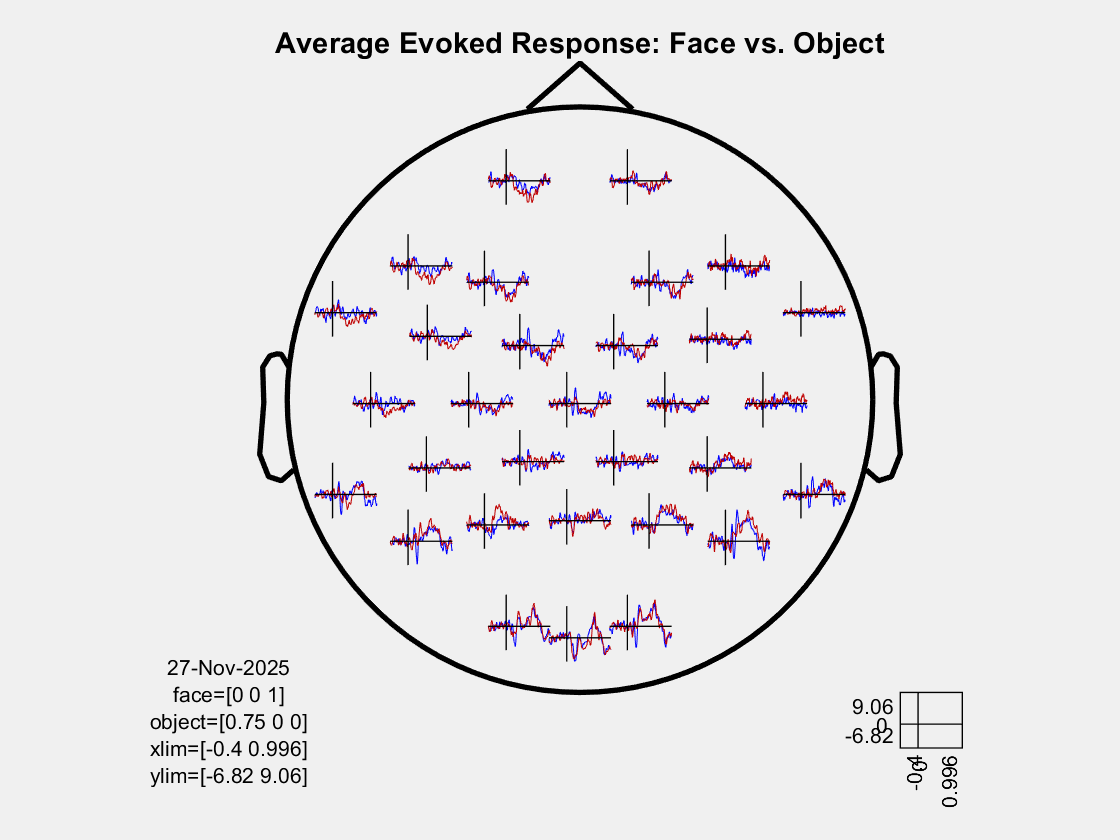

% ft_multiplotER(cfg, erp_vis_all);
title('Average Evoked Response: Face vs. Object');

% display the names of all channels
disp(ft_data1.label)

**Occipital -> P1 (Detection of Visual Stimulus)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


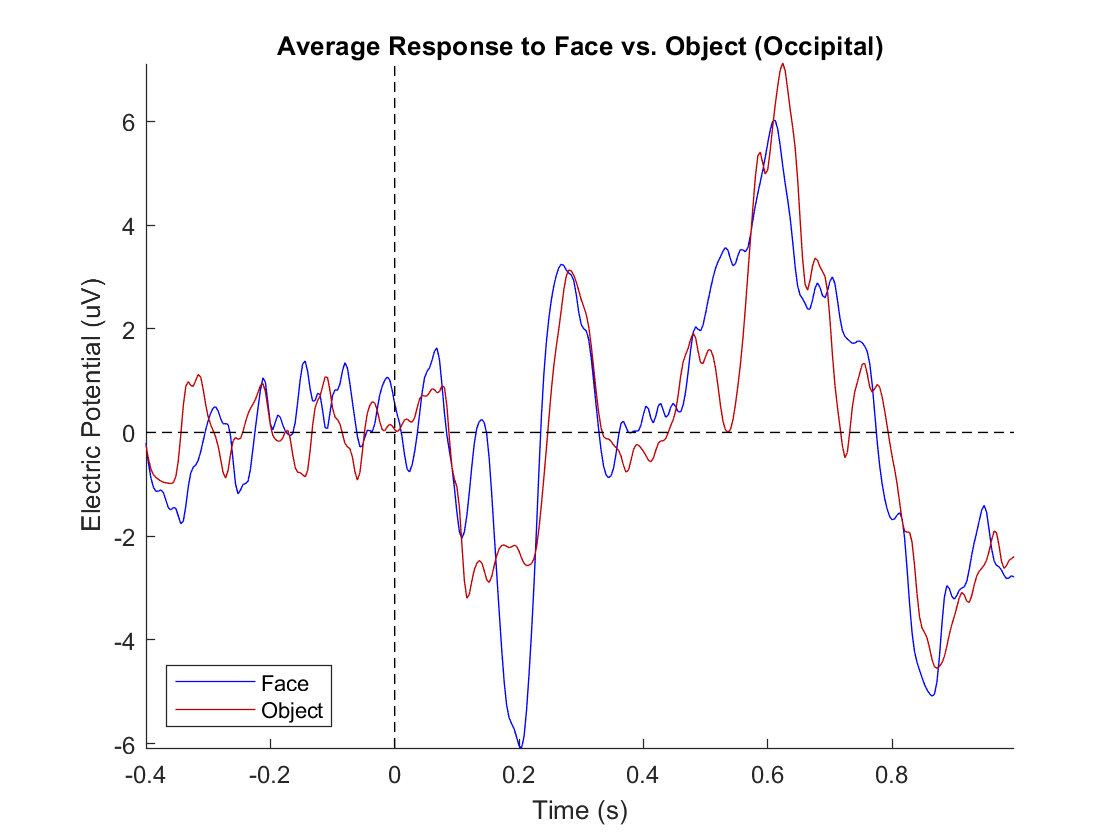

occip = {'O1', 'O2', 'Oz'};
plot_ERP_func(occip,face,object,'Face','Object','Average Response to Face vs. Object (Occipital)');

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


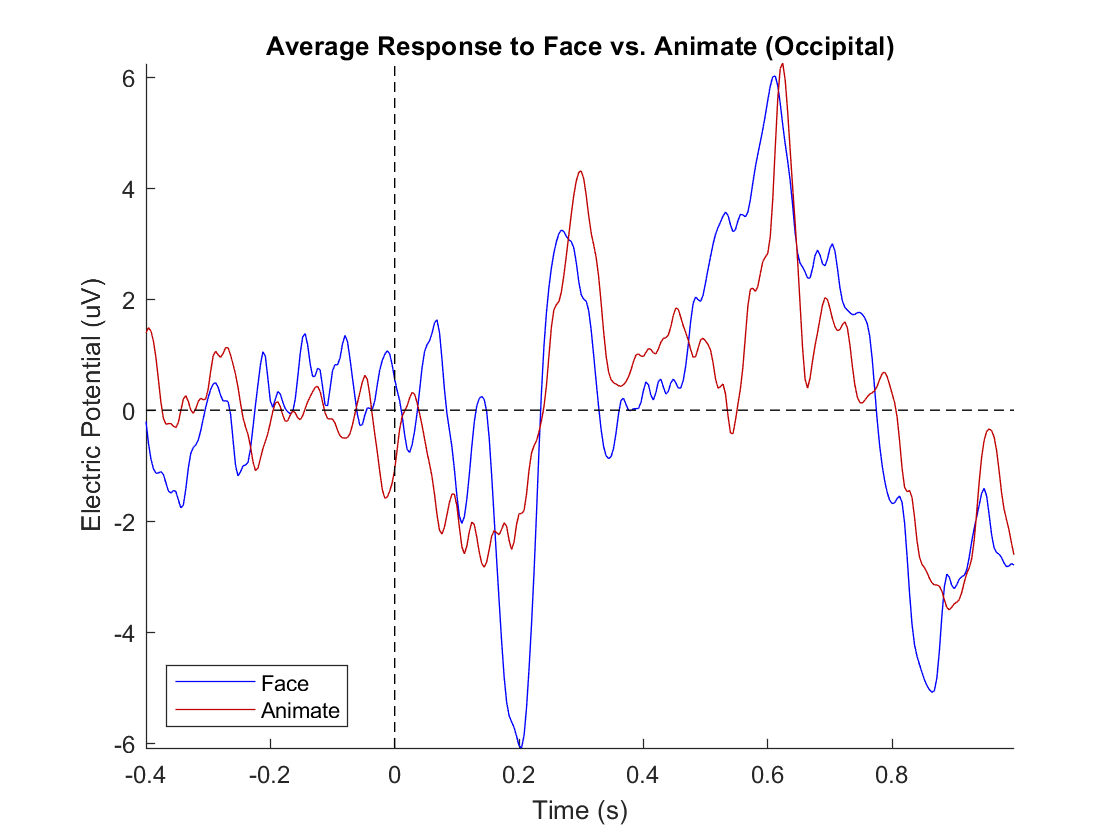

plot_ERP_func(occip,face,anim,'Face','Animate','Average Response to Face vs. Animate (Occipital)');

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


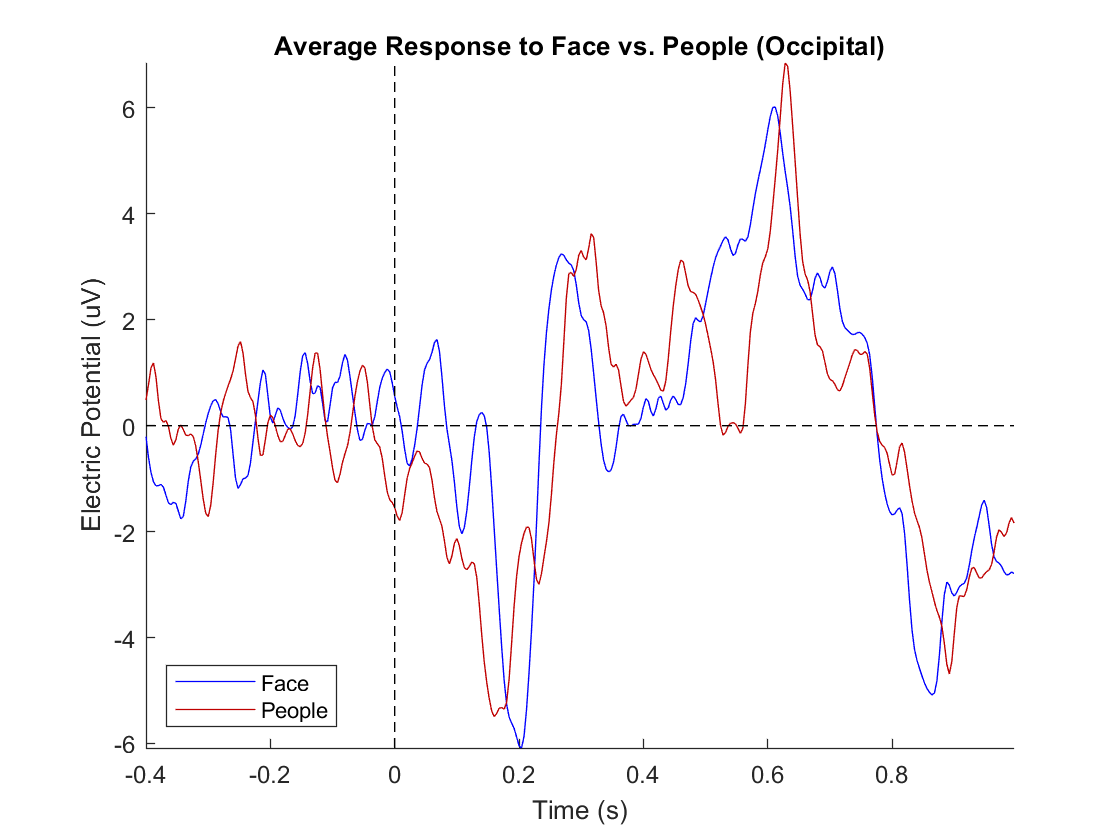

plot_ERP_func(occip,face,people,'Face','People','Average Response to Face vs. People (Occipital)');

**Occipital-Temporal -> N170 (Detection of a face)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


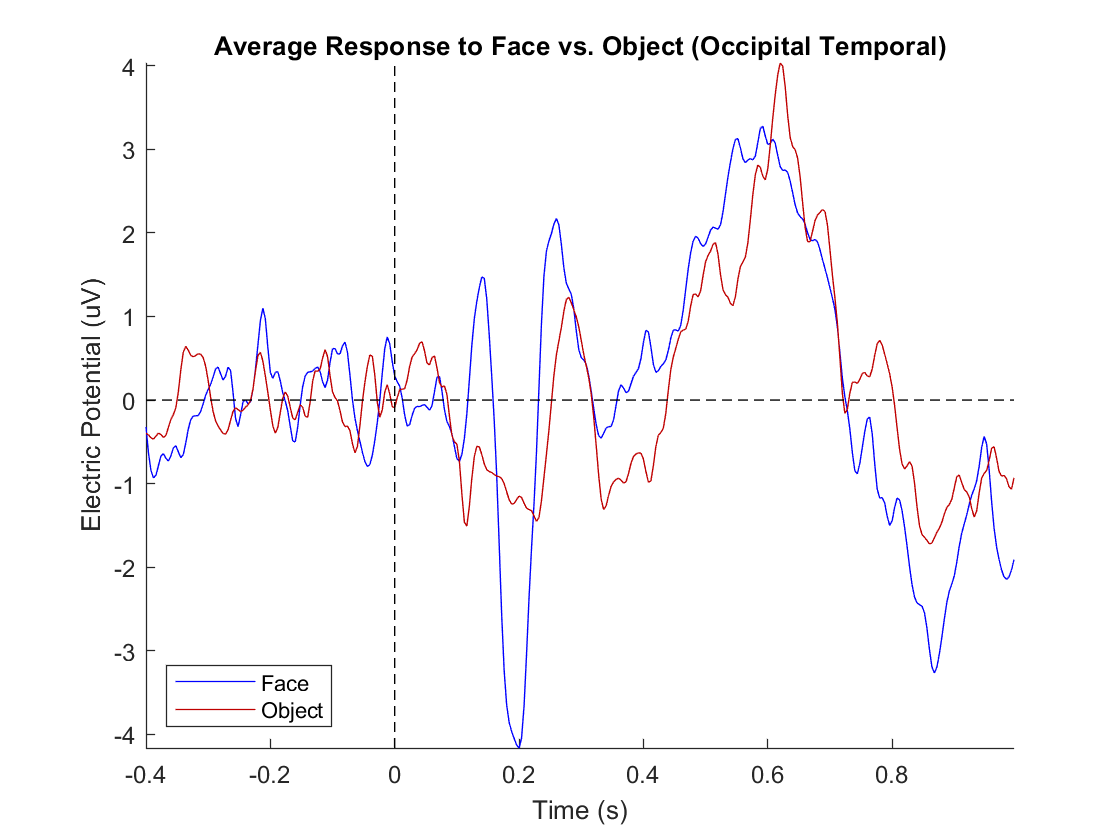

% visualize
occip_temp = {'O1', 'O2', 'Oz','T7','T8','TP9','TP10'};
plot_ERP_func(occip_temp,face,object,'Face', 'Object','Average Response to Face vs. Object (Occipital Temporal)');

**Central-Frontal -> N2 (further processing or inhibition)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


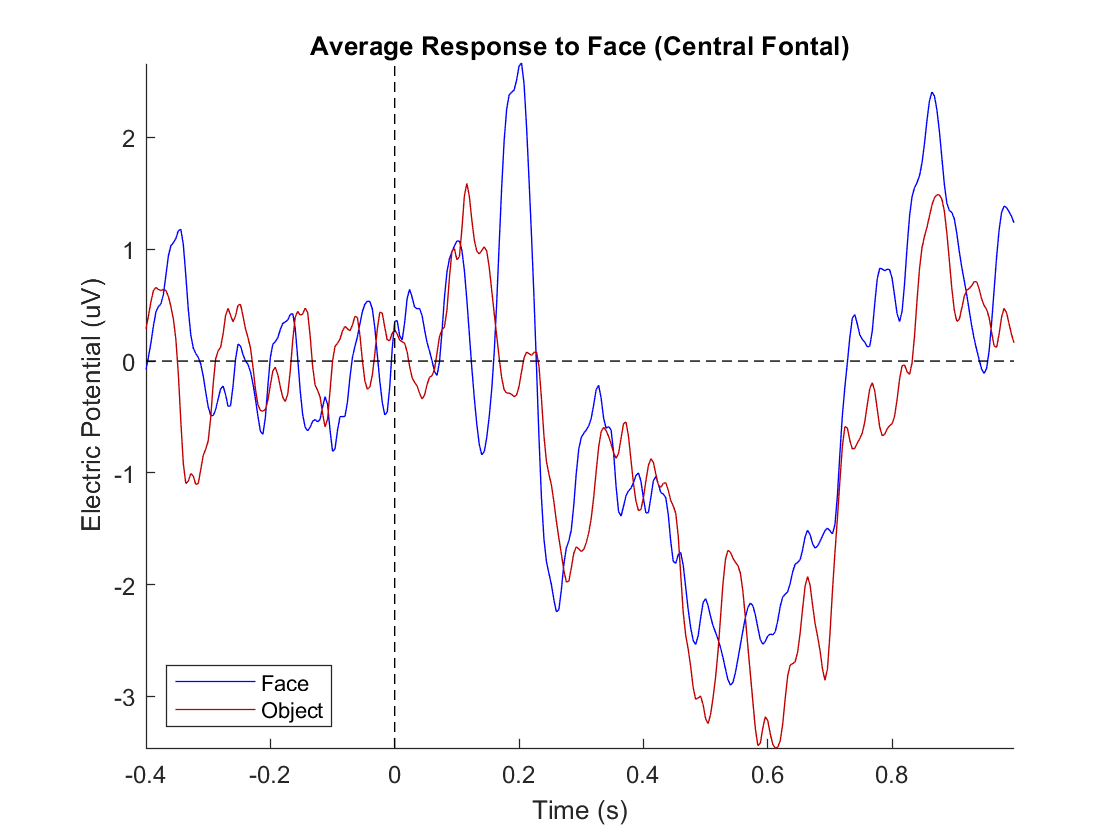

cent_front = {'Fp1','FP2','F9','F7','F3','F4', 'F8','FC5','FC1','FC2','FC6','C3','C4','Cz'};
plot_ERP_func(cent_front,face, object,'Face', 'Object','Average Response to Face (Central Fontal)');

**Central -> N400 (semantic integration)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


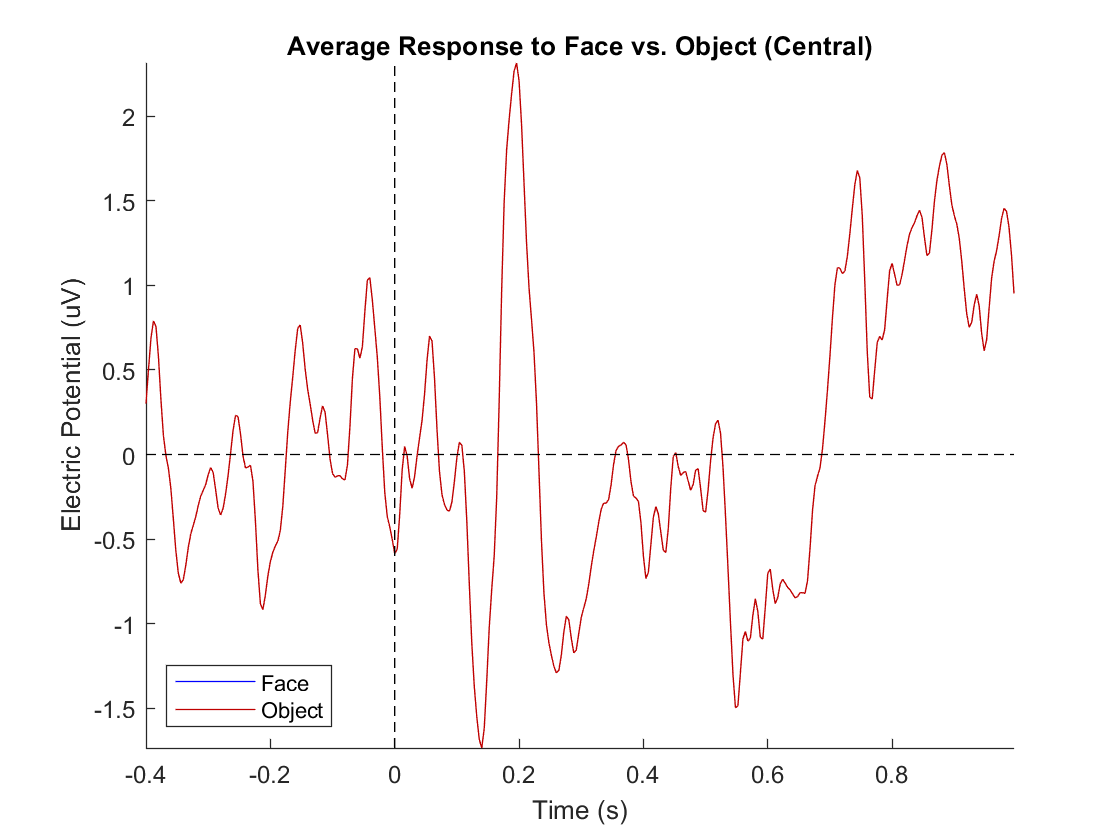

cent = {'C3','C4','Cz','CP1','CP5', 'CP6', 'CP2'};
plot_ERP_func(cent,face,face,'Face', 'Object','Average Response to Face vs. Object (Central)');

## Multiple ERP topo plots


cfg           = [];
% cfg.operation = 'x1-x2';
cfg.parameter = 'avg';

% difference_wave1 = ft_math(cfg, grandavg_nnf, grandavg_mnf);
% difference_wave2 = ft_math(cfg, grandavg_mmf, grandavg_mnf);
% difference_wave = ft_math(cfg, face);

difference_wave = face;
cfg = [];
cfg.xlim = [-0.2:0.05:0.8];
% cfg.ylim = [15 20];
cfg.zlim = [-4 4]; % universal_value for all face conditions and subjects = [-3 3], house = [-6 6]
% cfg.baseline = [-0.2 0];
% cfg.baselinetype = 'absolute';
cfg.layout = layout;
cfg.comment = 'xlim';
cfg.colormap = 'jet';%'*RdBu';
cfg.commentpos = 'title';
% cfg.highlight = 'on';
% cfg.highlightchannel = find(stat_bonferroni.prob<0.05);
figure; 
ft_topoplotTFR(cfg,difference_wave);%difference_wave

the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds
the call to "ft_topoplotTFR" took 7 seconds


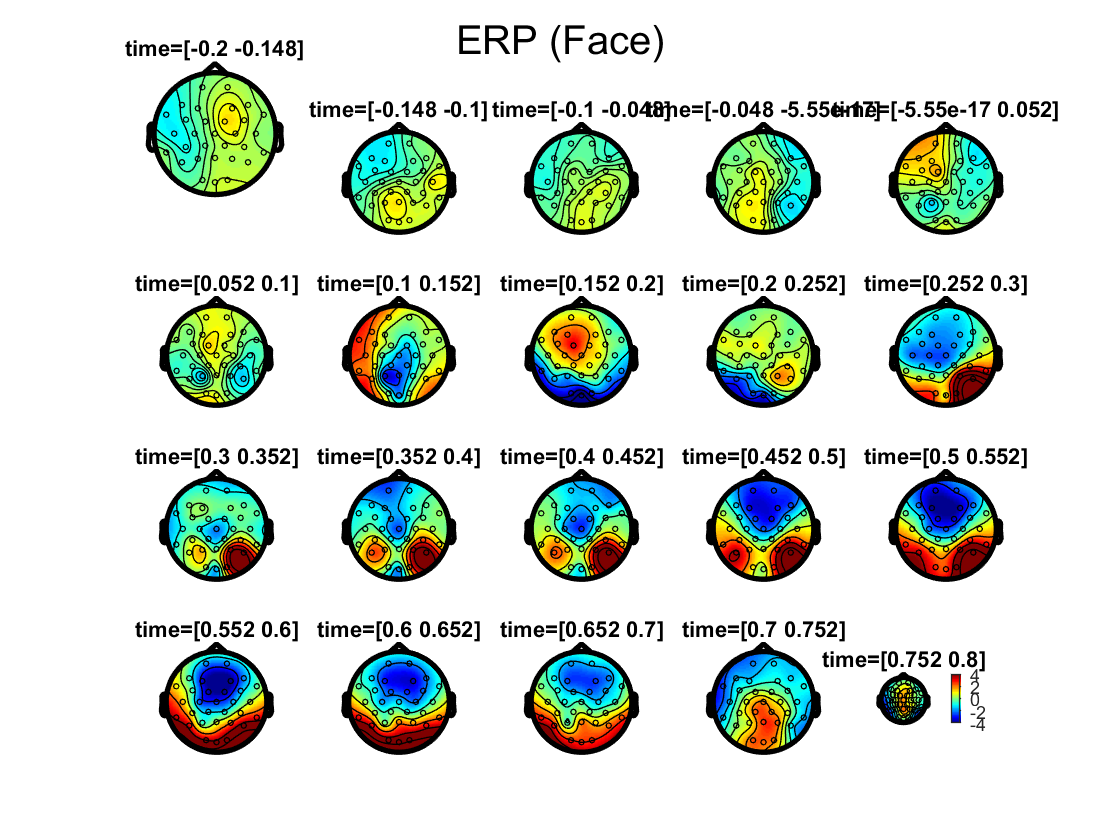

colorbar;
hold on
% sgtitle('Unexpected - Expected (Face)')
sgtitle('ERP (Face)')% (Conventional vMMN) (Expectation Effect) (Repetition Effect)

cfg           = [];
% cfg.operation = 'x1-x2';
cfg.parameter = 'avg';

% difference_wave1 = ft_math(cfg, grandavg_nnf, grandavg_mnf);
% difference_wave2 = ft_math(cfg, grandavg_mmf, grandavg_mnf);
% difference_wave = ft_math(cfg,object);
difference_wave = anim;
cfg = [];
cfg.xlim = [-0.2:0.05:0.8];
% cfg.ylim = [15 20];
cfg.zlim = [-4 4]; % universal_value for all face conditions and subjects = [-3 3], house = [-6 6]
% cfg.baseline = [-0.2 0];
% cfg.baselinetype = 'absolute';
cfg.layout = layout;
cfg.comment = 'xlim';
cfg.colormap = 'jet';%'*RdBu';
cfg.commentpos = 'title';
% cfg.highlight = 'on';
% cfg.highlightchannel = find(stat_bonferroni.prob<0.05);
figure; 
ft_topoplotTFR(cfg,difference_wave);%difference_wave

the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 1 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 1 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotTFR" took 0 seconds
the call to "ft_topoplotTFR" took 10 seconds


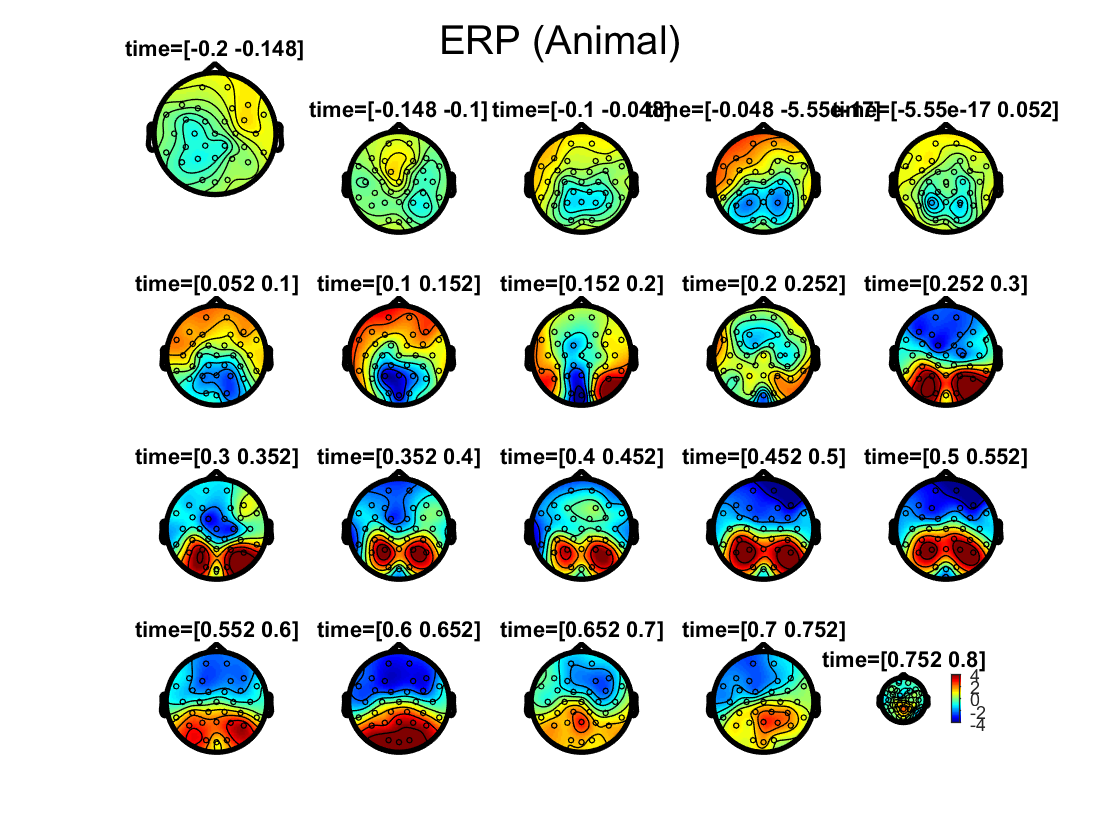

colorbar;
hold on
% sgtitle('Unexpected - Expected (Face)')
sgtitle('ERP (Animal)')